# **Semantic Segmentation - Galapagos Lavas**

**Drone Imagery**

## Setup and Labeling

clear all

home = false; %Set to true if working from home, false if working from school. 

%Set file paths for images to pixel label

if home
    cd 'F:\Research\Galapagos'
    filepath = ('F:\Research\Galapagos\Galapagos_imagery\Datastore');
else
    cd 'D:\Research\Galapagos'
    filepath = ('D:\Research\Galapagos\Galapagos_imagery\Datastore');
end


%create datastore
imds = imageDatastore(filepath,'FileExtensions','.jpg');

%open Image Labeler to create pixel labels and save session. Comment out
%once labels and session are saved. 

%imageLabeler(imds)

    %labels are stored in 'galLabels.mat'
    %session is stored in 'galLabelingSession'
    
load galLabels.mat labelDefs;
galLabels = labelDefs;

## Image Labeler

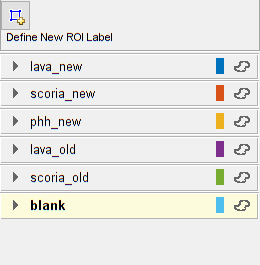

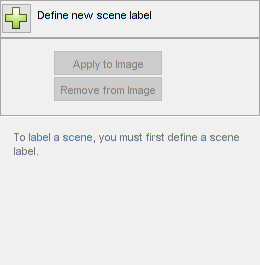

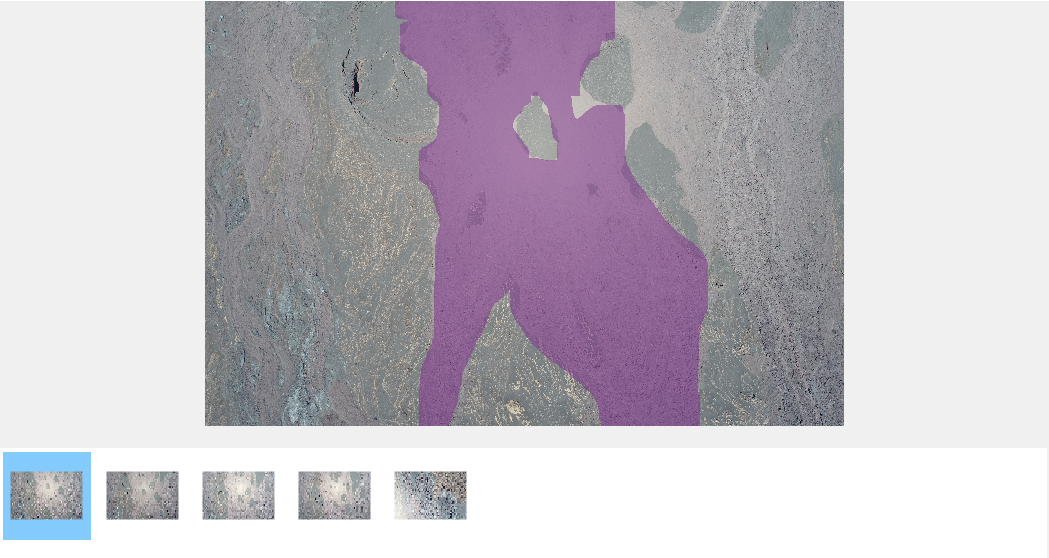

imageLabeler('galLabelingSession.mat'); %open image labeler, export ground truth

%Export ground truth from image labeler (gTruth.mat is output)

load gTruth.mat

% create pixel label datastore

pxds = pixelLabelDatastore(gTruth);

%create pixel label image datastore for training

pximds = pixelLabelImageDatastore(imds,pxds);  %%%needs to be same number of files

Error using images.internal.datastore.PixelLabelImageDatastore (line 214)
imds and pxds must have the same number of Files.

Error in pixelLabelImageDatastore (line 195)
            this = this@images.internal.datastore.PixelLabelImageD


%set training options

options = trainingOptions('sgdm','InitialLearnRate',1e-3, ...
    'MaxEpochs',20,'VerboseFrequency',10);

## Create Segmentation Network

% Set classes to names of lava classes
classes = galLabels{1:6,"Name"};

numClasses = numel(classes);

%Set network image input size
imageSize = [64 64 3]; 

%create lgraph object from SegNet layers (uninitalized encoder depth)
lgraph = segnetLayers(imageSize,numClasses,5);

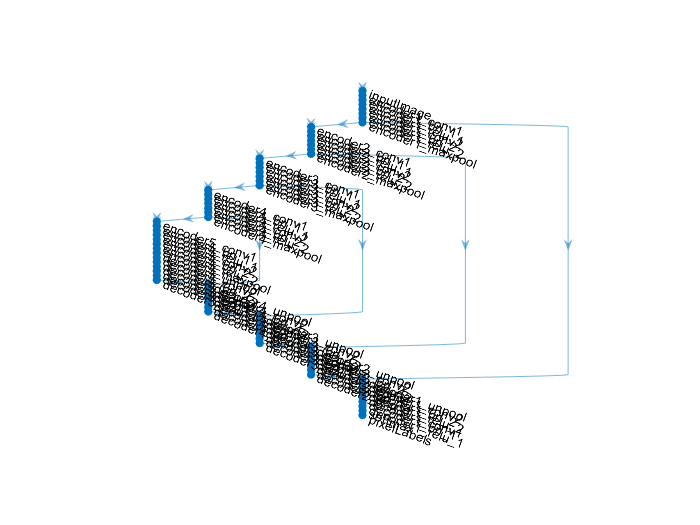

plot(lgraph)

hAxes = gca; 
axis off

## Train Network

% Train neural network using pixel image datastore and pre-defined
% architecture

net = trainNetwork(pximds,lgraph,options)

Undefined function or variable 'pximds'.

## Run trained network on test images

pxdsResults = semanticseg(testimds,net,'WriteLocation',tempdir);

## Evaluate Semantic Segmentation data set against ground truth

ssm = evaluateSemanticSegmentation(pxdsResults, pxdsTruth)

ssm.ClassMetrics

ssm.NormalizedConfusionMatrix